# 初期設定

rng('default') %seedを初期値に戻す。再現できる
random('inversegaussian',0.1,1)

ans = 0.0607

tdata=0:0.5:11; %乱数はt=11まで発生させる 23
train_tdata = 0:0.5:10

train_tdata =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


test_tdata = 10.5:0.5:11;
intervaldata = 1:1:(length(train_tdata)-1);
length(tdata)-1;%区間数 22
n = 25; %サンプルサイズ設定
type = 2; %増分は1、累積は2

# シミュレーションデータ作成、区間ごとのパラメータ推定

data = zeros(n,length(tdata)-1);
% とりあえず、シミュレーション数1回で組んでみる
%1シミュレーションのデータ生成
for i = 1:n
    for j = 1:length(tdata)-1
        mu = 0.1 * (lambda1(tdata(j+1))-lambda1(tdata(j)));
        lambda = 1 * (lambda1(tdata(j+1))-lambda1(tdata(j)))^2;
        data(i,j) = random('inversegaussian',mu,lambda);
    end
end
train_data = data(:,1:20);
test_data = data(:,21:22);
[tr_rows,tr_cols]= size(train_data);


%区間ごとの最尤推定
mulist = zeros (1,tr_cols);
for i=1:tr_cols
mlelist = mle(train_data(:,i) ,'distribution','InverseGaussian');
mulist (i) = mlelist (1);
end
mulist

mulist =     0.0917    0.1941    0.3869    0.7001    1.0347    1.4253    1.9961    2.5681    3.1939    3.9478    4.7362    5.6208    6.5545    7.5920    8.6238    9.8649   11.0338   12.3654   13.9753   15.3503


%増分の時
if type == 1
    gprMdlinc = fitrgp(transpose(intervaldata),transpose(mulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
    lambdainc = transpose(predict(gprMdlinc,intervaldata.')); 
    lambdaf = lambdainc; %lambdafは縦ベクトル
end

%累積の時
if type == 2
    cummulist = cumsum([0 mulist]);
    gprMdlcum = fitrgp(transpose(train_tdata),transpose(cummulist),'Basis','linear',...
      'FitMethod','exact','PredictMethod','exact');
    lambdacum = transpose(predict(gprMdlcum,tdata.'));
    lambdacumjump = zeros(1,tr_cols);
    for i=1:tr_cols
    lambdacumjump(i) = lambdacum(i+1)-lambdacum(i);
    end
    lambdaf = lambdacumjump; %lambdafは縦ベクトル
end

nu = optimvar("nu","LowerBound",0);
obj = fcn2optimexpr(@LLIG_M4gp3,train_data,lambdaf,nu);
prob = optimproblem("Objective",obj,"ObjectiveSense","maximize");
x0.nu=1;
sol = solve(prob,x0);


fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>


est_nu = sol.nu

est_nu = 90.4300

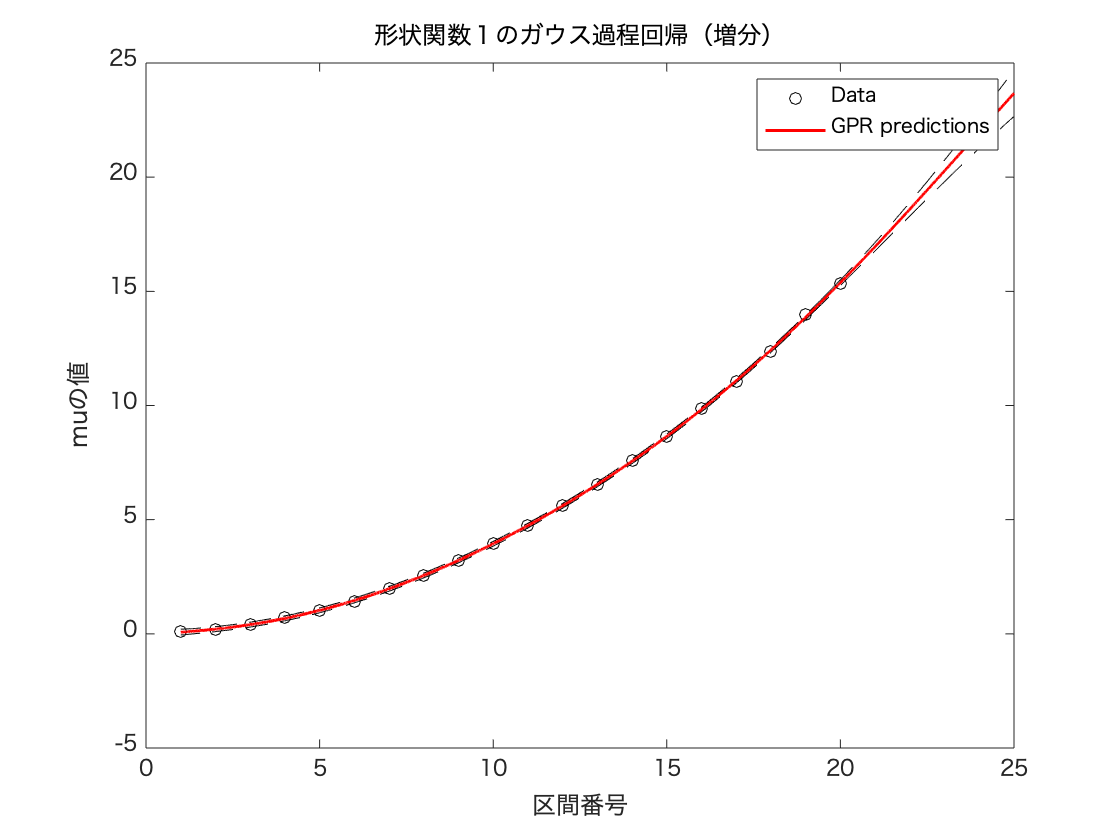

x = linspace(1,25,10000)';
[ypred,~,yci] = predict(gprMdlinc,x);
plot(1:1:20,mulist,'ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
xlabel('区間番号');
ylabel('muの値');
title('形状関数１のガウス過程回帰（増分）');
legend('Data','GPR predictions');
hold off

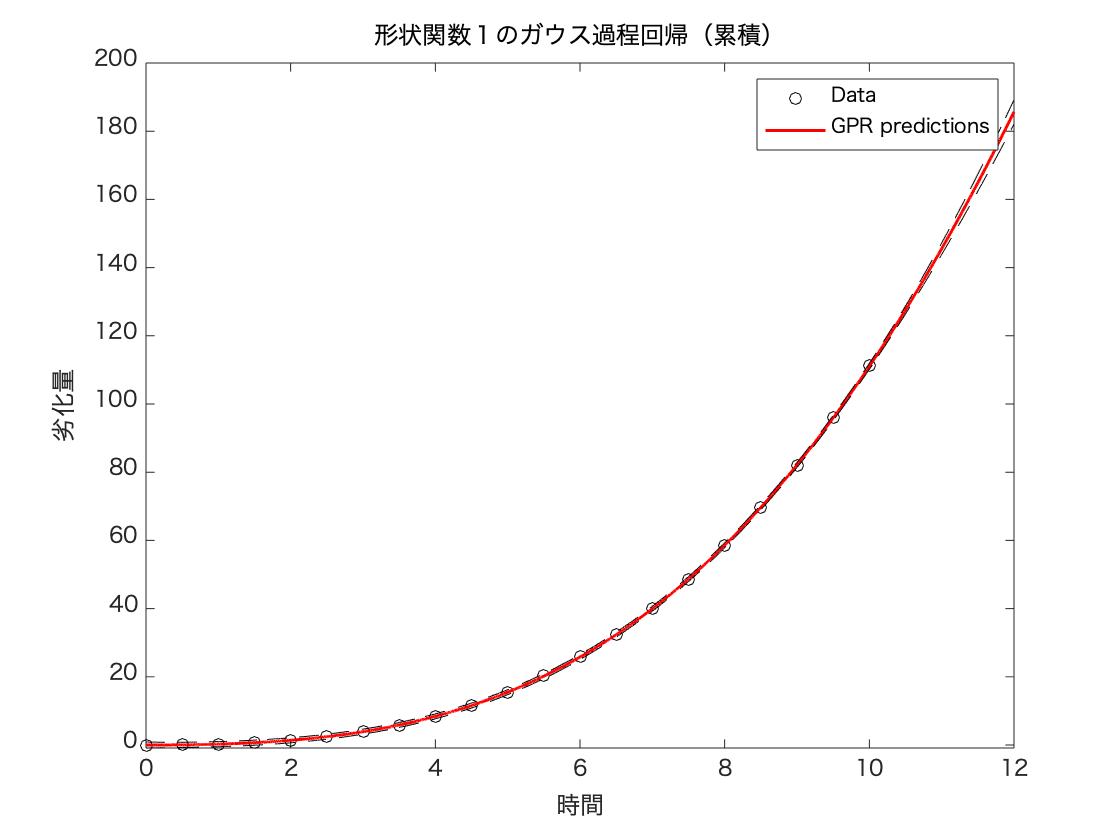

%シミュレーションデータ累積プロット
cummulist = cumsum([0 mulist]);
x = linspace(0,12,10000)';
[ypred,~,yci] = predict(gprMdlcum,x);
plot(0:0.5:10,cummulist,'ko');
hold on;
plot(x,ypred.','r','LineWidth',1.5);
plot(x,yci(:,1),'k--');
plot(x,yci(:,2),'k--');
hold off

xlabel('時間');
ylabel('劣化量');
title('形状関数１のガウス過程回帰（累積）');
legend('Data','GPR predictions');
hold off

%mseを出すためにnuを求める必要はないのでは？
%増分の時
preds = predict(gprMdlinc,(1:1:(length(tdata)-1)).').'; %増分の予測値
cum_preds = cumsum([0 preds]);
pred22 = repmat(cum_preds(23),tr_rows,1);
zero_v = zeros(n,1);
cum_data = cumsum([zero_v data],2);
mean((pred22-cum_data(:,23)).^2)%これがMSE

ans = 1.1837

zero_v = zeros(n,1);
cum_data = cumsum([zero_v data],2); %シミュレーションデータの累積
pred = repmat(predict(gprMdlcum,11),tr_rows,1);
mean((pred-cum_data(:,23)).^2)%これがMSE

ans = 2.3793

%1000回シミュレーションを行う

rng('default')
mselist = [];
for i = 1:10
    mse = sim_fun(25,2,4);
    mselist(i) = mse;
end


fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>

fmincon を使用して問題を解決しています。

局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が<a h


fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>



fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>

fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が<a href = "m


fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>


mselist

mselist =     0.0013    0.0012    0.0016    0.0007    0.0009    0.0009    0.0009    0.0005    0.0005    0.0021


mean(mselist)

ans = 0.0011

mse = sim_fun(25,2,1)


fmincon を使用して問題を解決しています。

制約を満たす局所的最小値が見つかりました。

目的関数が最適性の許容誤差値の範囲内の実行可能な方向
において非減少であり、制約が制約の許容誤差値の範囲内で
満たされているため、最適化は完了しました。

<停止条件の詳細>


mse = 4.3802

rep = 7;
sim_test = data_create(25,rep,1);

writematrix(sim_test,'sim.txt','Delimiter','tab')
data = readmatrix("sim.txt");
sim_data = zeros(25,22);
for i = 1:rep
    if i==1
        sim_data(:,:,i) = data(:,1:22); 
    else
        sim_data(:,:,i) = data(:,(22*(i-1)+1):(22*i));
    end
end
size(sim_data)

ans =     25    22     7


[m,n]=size(data);
n/rep

ans = 22

%-------------------------------------------
%以後関数

function y = lambda1(t)
    %係数設定
    a1 = 1;
    a2 = 1;
    a3 = 1;
    %形状関数
    y = a1*t + a2*t^2 + a3*t^3;
end

function y =lambda2(t)
    %係数設定
    a1 = 1;
    %形状関数
    y = exp(a1 * t^2) -1;
end

function y =lambda3(t)
    %係数設定
    
    %形状関数
    y = log(1+t);
end

function y = lambda4(t)
    %係数設定
    k = 1
    b = 10
    c = 0.5
    %形状関数
    y = k*(1/(1+b*exp(-c* t))- 1/(1+b))
end